## Matlab jako kalkulačka

1. Určete pořadí v jakém se vyhodnotí následujcí příklady.

2/3*3           % (2 / 3) * 3 = 2 

ans = 2

3*4-5^2*2       % (3 * 4) - 5^2 * 2 = -38

ans = -38

(3*4-5^2*2) * 3 % (3 * 4 - 5^2 * 2) * 3 = -104

ans = -114

2. Určete hodnotu následujících výrazů.

0 * 0/1         % 0 * (0/1)

ans = 0

1 ^ (1/0) + 1   % (1/0) => Inf (infinity)

ans = 2

1/0 + 1         % Inf

ans = Inf

## Proměnné a datové typy

3. Proč je rozdíl mezi vypičtenými hodnotami výrazů, když sin (2* k * pi) by měli mít stejné hodnoty?

Yes, it is because π is a value that cannot be represented precisely using a finite binary [floating point number](http://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html). This is also shown in the [`sind`](http://www.mathworks.com/help/matlab/ref/sind.html) documentation: https://nl.mathworks.com/matlabcentral/answers/229601-sin-2-pi-vs-sind-360

sin(2 * pi)

ans = -2.4493e-16

sin(1000 * pi)

ans = -3.2142e-13

1 + eps

ans = 1.0000

1 + 1e-16

ans = 1

2e307

ans = 2.0000e+307

2e308

ans = Inf

1e-323

ans = 1.0000e-323

1e-324

ans = 0

4. Jaký je rozdíl mezi výrazy?

i = 10

i = 10

1 + 1 * i % reálné číslo 11

ans = 11

1 + 1i    % komplexní číslo (1.0, 1.0) = (Re=1.0, Im=1.0)

ans = 1.0000 + 1.0000i

## Vektory a matice

u = [6 2 4]

u =      6     2     4


v = [3 -2 3 0]

v =      3    -2     3     0


w = [3; 4; 2; -6]

w =      3
     4
     2
    -6



% u * v  % Skalární součin je definován jen pro vektory stejné dimenze.
u' * v % Maticové náse 

ans =     18   -12    18     0
     6    -4     6     0
    12    -8    12     0


% u * v'
v * w % Skalární součin řádkového a sloupcového vektoru.

ans = 7


v = [1 3 8 9 7 9 21 3.5]

v =     1.0000    3.0000    8.0000    9.0000    7.0000    9.0000   21.0000    3.5000



v(3)     % => 8

ans = 8

v(end)   % => 3.5

ans = 3.5000

v(1:2:4) % => 1, 8

ans =      1     8


v([1:3,end-2:end])

ans =     1.0000    3.0000    8.0000    9.0000   21.0000    3.5000


7. Vytvořte vektor pomocí tečkové notace.

x = [0:0.1:2]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y = x.*sin(x * pi)

y =          0    0.0309    0.1176    0.2427    0.3804    0.5000    0.5706    0.5663    0.4702    0.2781    0.0000   -0.3399   -0.7053   -1.0517   -1.3315   -1.5000   -1.5217   -1.3753   -1.0580   -0.5871   -0.0000


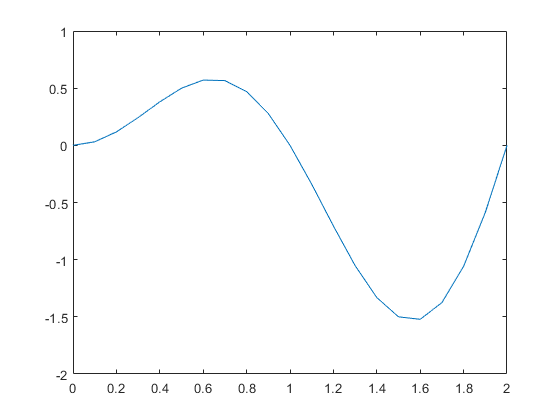

plot(x, y)

8. Otočte pomocí dvojtečkové notace vektor

v = [1 3 8 9 7 9 21 3.5]

v =     1.0000    3.0000    8.0000    9.0000    7.0000    9.0000   21.0000    3.5000


v(end:-1:1)

ans =     3.5000   21.0000    9.0000    7.0000    9.0000    8.0000    3.0000    1.0000


% nebo
v(length(v):-1:1)

ans =     3.5000   21.0000    9.0000    7.0000    9.0000    8.0000    3.0000    1.0000


9. Odhadněte limitu

11. Pro náhodné matice určete hodnoty.

rng(123) % https://nl.mathworks.com/help/matlab/math/generate-random-numbers-that-are-repeatable.html
A = rand(3, 4)

A =     0.6965    0.5513    0.9808    0.3921
    0.2861    0.7195    0.6848    0.3432
    0.2269    0.4231    0.4809    0.7290


B = rand(5, 4)

B =     0.4386    0.1755    0.7245    0.2283
    0.0597    0.5316    0.6110    0.2937
    0.3980    0.5318    0.7224    0.6310
    0.7380    0.6344    0.3230    0.0921
    0.1825    0.8494    0.3618    0.4337


% A * B % matice se liší v počtu řádků a sloupců
A * B'

ans =     1.2022    1.0491    1.5264    1.2166    1.1203
    0.8262    0.9188    1.2078    0.9204    1.0600
    0.6886    0.7464    1.1228    0.6583    0.8910


13. 

A = rand(5, 4);
A'

ans =     0.4309    0.4937    0.4258    0.3123    0.4264
    0.8934    0.9442    0.5018    0.6240    0.1156
    0.3173    0.4148    0.8663    0.2505    0.4830
    0.9856    0.5195    0.6129    0.1206    0.8263


[A;zeros(4)']

ans =     0.4309    0.8934    0.3173    0.9856
    0.4937    0.9442    0.4148    0.5195
    0.4258    0.5018    0.8663    0.6129
    0.3123    0.6240    0.2505    0.1206
    0.4264    0.1156    0.4830    0.8263
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
